# Feature Extraction for Pump Fault Classification

To train a machine learning model to detect faults in operational data, you need to extract the best features to train your model. In this example, you will learn to interactively explore, extract, and rank time- and frequency-domain features interactively using the Diagnostic Feature Designer app. Then, you will generate a MATLAB function that can regenerate these features on new data, and use them to train a machine learning model to identify faults in new pump data.

## Setup

### 1. Load Saved Dataset

Using this [example](https://www.mathworks.com/help/predmaint/ug/multi-class-fault-detection-using-simulated-data.html) (`nPerGroup=30)`, we generate synthetic flow and pressure data for a triplex pump in normal or faulty states. There are 3 possible fault types: leaking seal, blocked inlet, and worn bearing. The combination of zero, one, or multiple faults together gives 8 possible fault code combinations **from 000 (no fault), 001, ... to 111 (all faults present together).**

The MAT file `pumpDataComplete` contains preprocessed data, uniformly resampled with the initial transients removed. Load this file to get started.

load pumpDataComplete.mat

### 2. Partition Data for Training and Testing

We will set aside 10% of the data for testing the predictive model. This helps prevent overfitting by testing our trained model on new data.

rng("default") % For reproducibility
holdOutTestData = 0.1;

c = cvpartition(pumpDataInMemory.faultCode,'HoldOut',holdOutTestData);
trainData = pumpDataInMemory(training(c),:);
testData = pumpDataInMemory(test(c),:);

## Extract Features Interactively using Diagnostic Feature Designer *A*pp

***Note: Once you open Diagnostic Feature Designer in MATLAB Online, it can be cumbersome to click back and forth between the app and this script. Consider using the ***[***HTML version***](matlab: web("HelperFiles/Work_FeatureExtraction.html","-browser"))*** of this script in another browser window to follow along.***

The Diagnostic Feature Designer app lets you interactively extract, visualize, and rank a variety of features from measured or simulated data.

### 3. Open Diagnostic Feature Designer

Start by opening the Diagnostic Feature Designer app from the **APPS** tab on the toolstrip, or by running the command `diagnosticFeatureDesigner` in the command window.

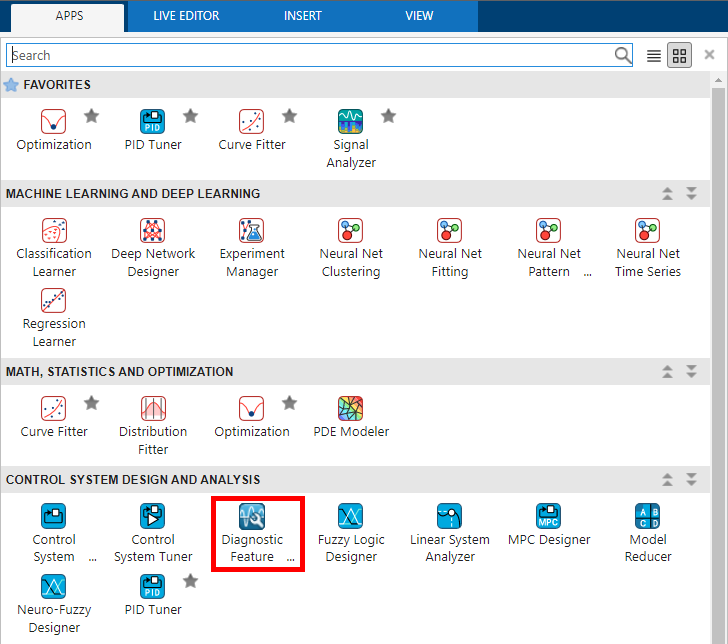

### 4. Load Data

Once opened, start a *New Session *and select the training data from the workspace:

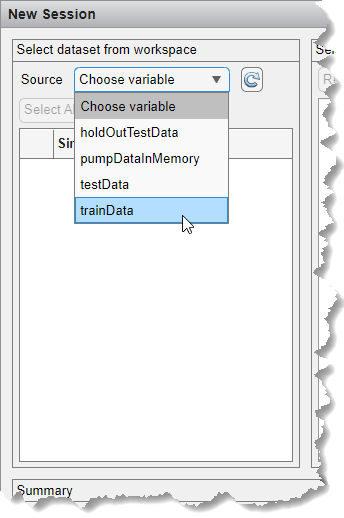

Data is loaded as a multi-member ensemble, since multiple datasets are stored in a single variable.

You can then review the various signals you are importing and provide a name to for the ensemble. Ensure that the `faultCode` variable is a **Condition Variable**. Condition variables indicate the *condition *of the machine and are used by the App for grouping and classification. Click **Import **when complete.

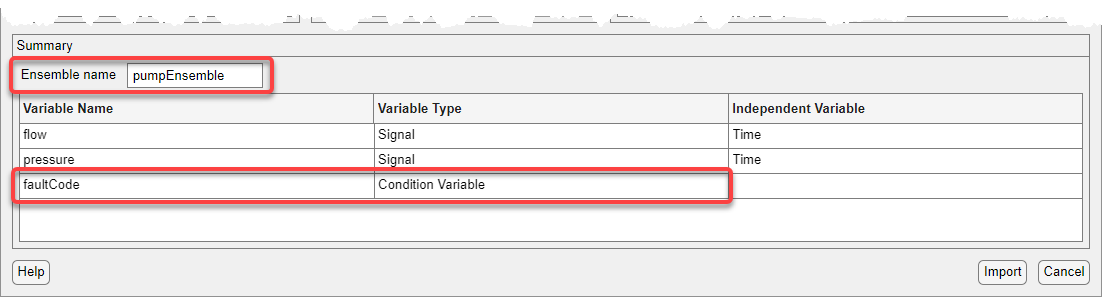

### 5. Plot Data

Once you have imported the dataset successfully, use the Signal Trace plot to visualize the flow and pressure signals. Select the data you want to visualize (e.g. `flow`) and click Signal Trace. (You can multi-select flow and pressure by holding down CTRL).

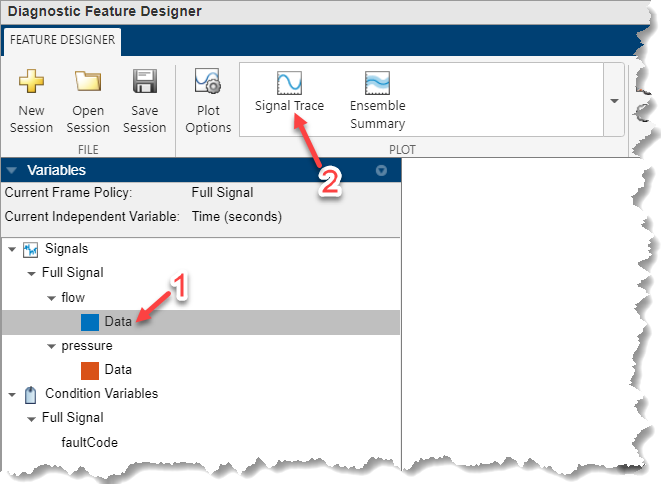

Do this for both the `flow` data and the `pressure` data. You may want to arrange your tabs (by dragging and dropping) to view the signals side by side:

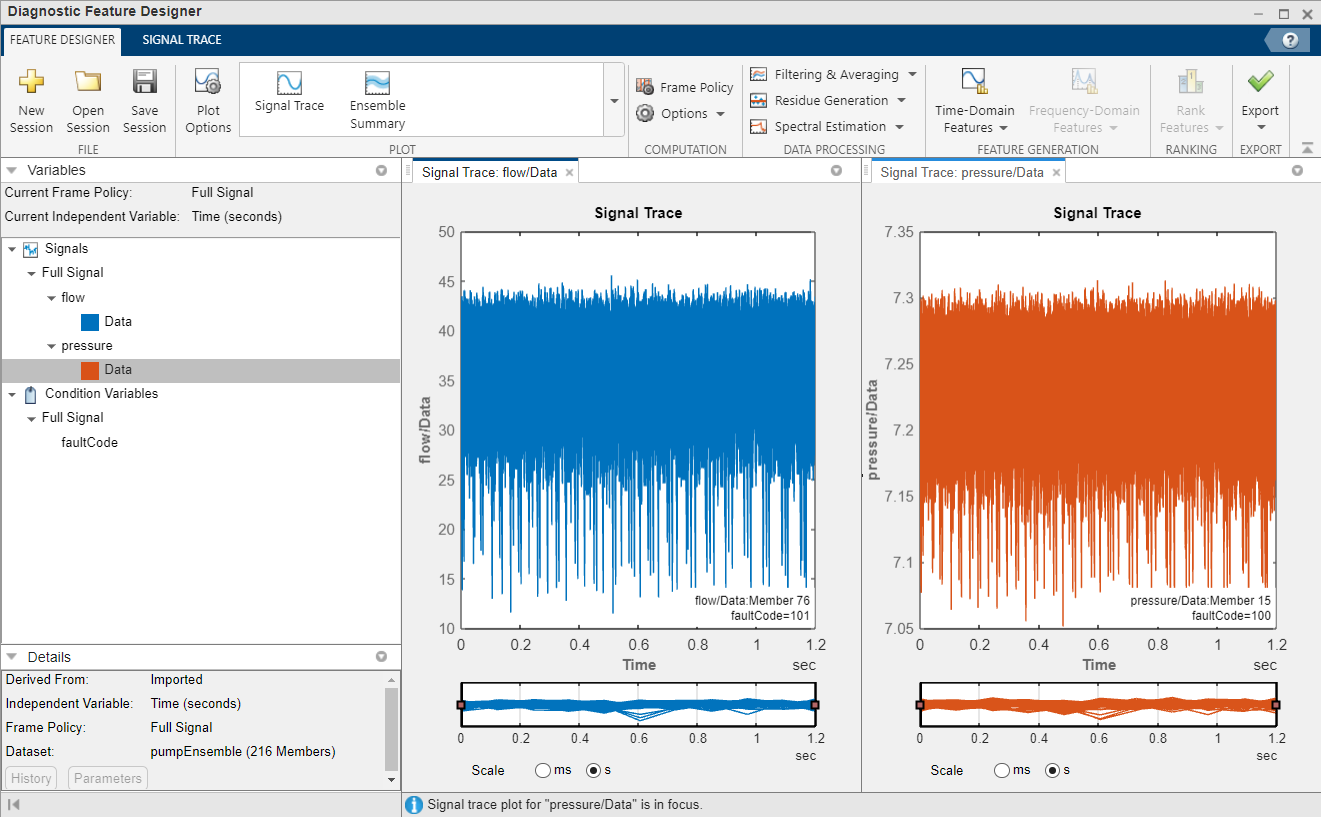

Go to the SIGNAL TRACE tab and group the signals by the condition variable, `faultCode`:

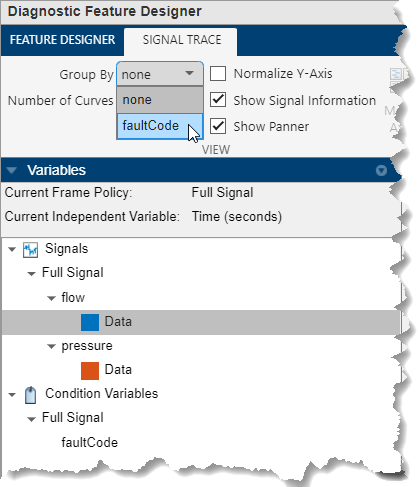

The resulting plot will then highlight data corresponding to different faults in different colors. You can use this plot to quickly determine if there are any clear differerences between different fault types. Try zooming in by dragging the edges of the panner below the plot. It's difficult to tell the difference in each fault code by eye! This is why we need to extract features that can better separate our data between the different fault codes.

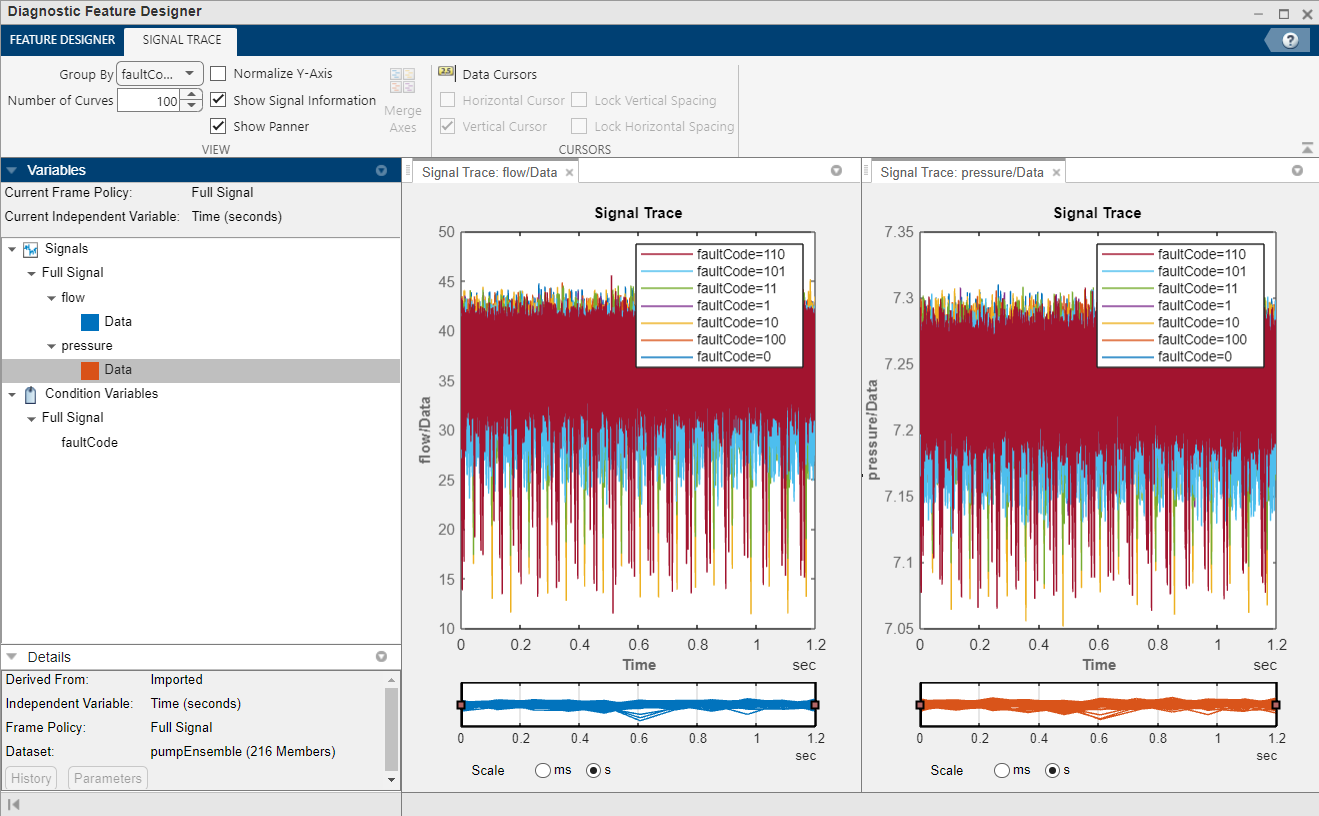

### 6. Extract Time-Domain Features

There are many types of features that can be explored in the app. Start by extracting some simple time-domain features using the entire signal, such as the mean value, standard deviation, etc. 

Open the *Time-Domain Features* dialog from the FEATURE DESIGNER tab and select *Signal Features *for the `flow` data:

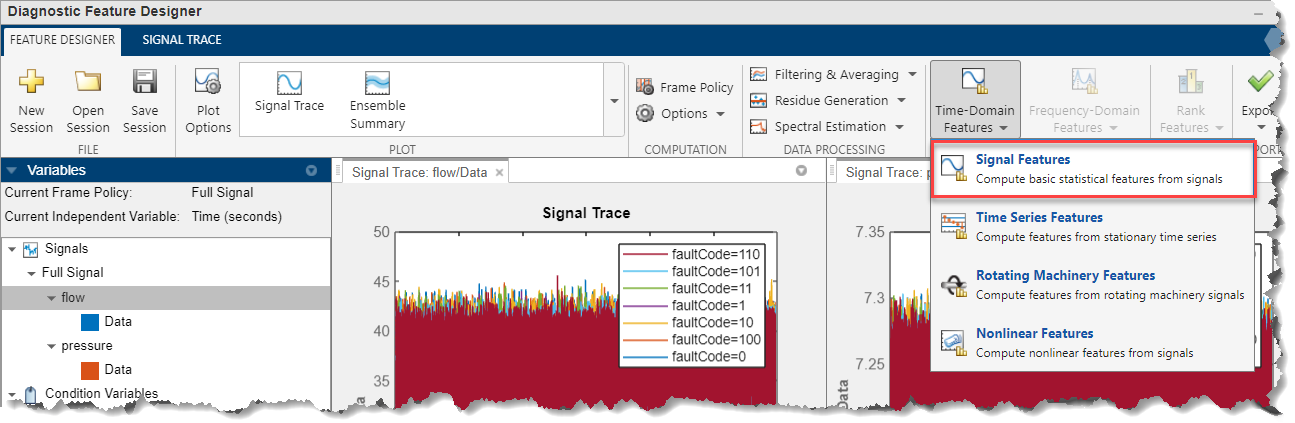

Check the features to be extracted and hit `Apply`:

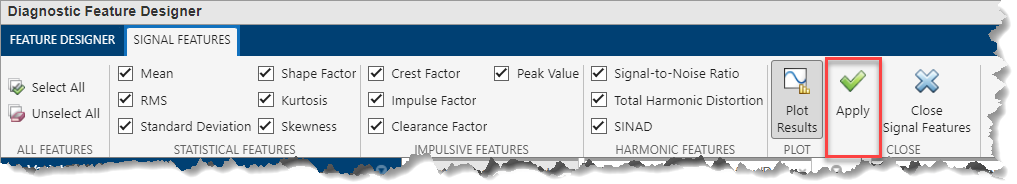

Statistical, impulsive and harmonic features have been computed and will now show up in the Feature Table in the Variables pane:

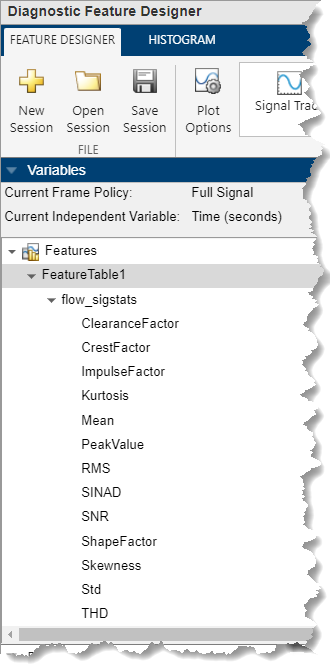

Once you have extracted time-domain features from the `flow` signal, **repeat the same process to extract time-domain features from the **`pressure`** signal. **

Once you've extracted time-domain features from both `flow` and `pressure `signals, review the computed features in the time domain by looking at the Histogram, Feature Table View or Feature Trace in the PLOT section:

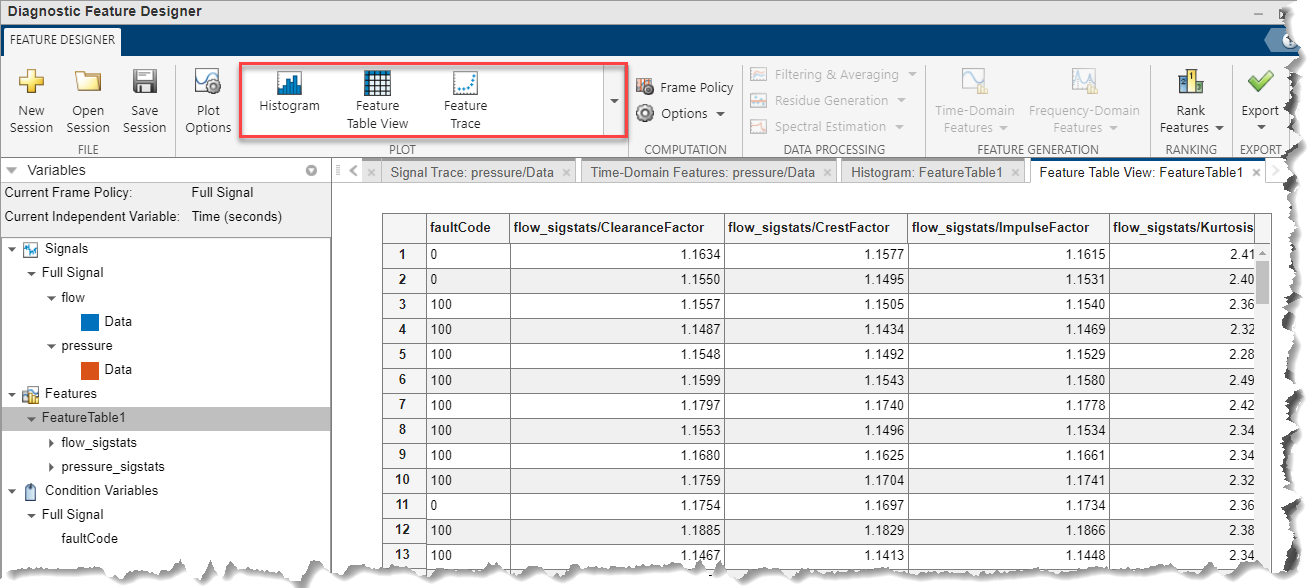

### 7. Compute Power Spectrum

You have now extracted some time-domain features for both the `flow` and `pressure` signals. But try zooming in on one of the signal trace plots using the panner at the bottom -- there appears to be some periodic behavior. So, it might be useful to take a look at features in the frequency domain as well.

In order to estimate frequency-domain features, you will first need to extract a **power spectrum **from each signal. There are several methods you can use to compute the power spectrum. In this case, we will compute an autoregressive model using a model order of 20. This fits an autoregressive model of the prescribed order to the data, then computes the spectrum of that estimated model. This reduces any overfitting to the raw data signal. 

Select the `flow` signal and open the *Spectral Estimation* dropdown menu and select *Autoregressive Model* within the *Power Spectrum *section: 

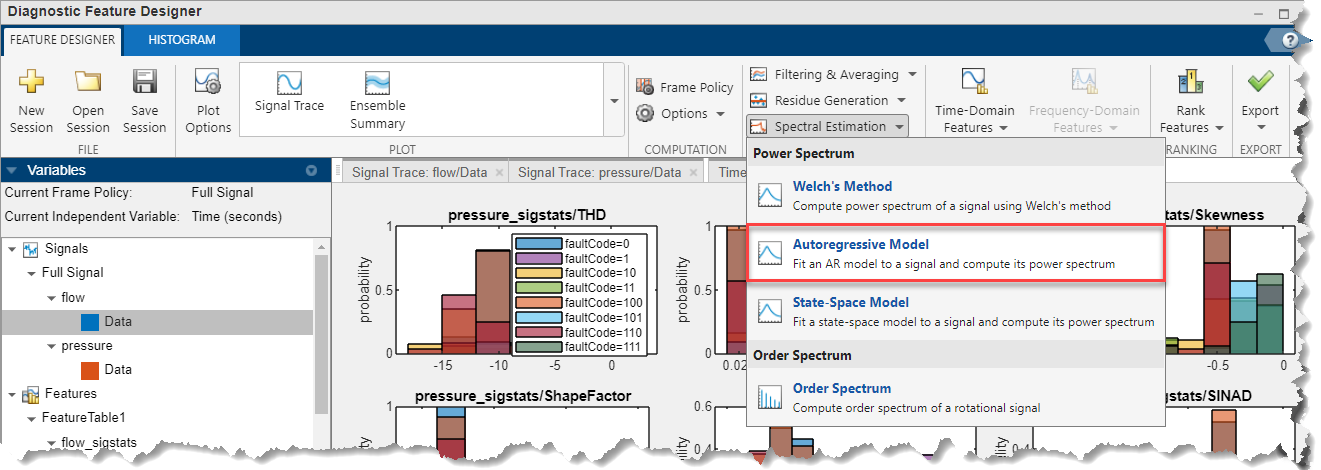

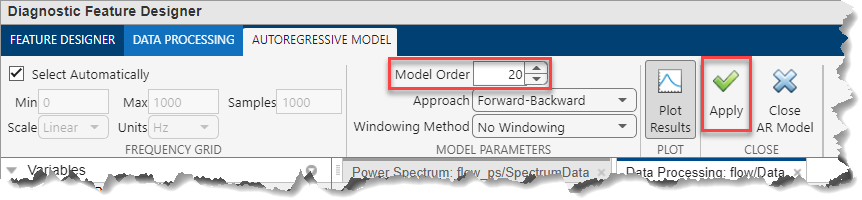

This computes the spectrum for each of the 216 flow signals in the training ensemble. In the POWER SPECTRUM tab, group spectral data by `faultCode` and choose the Linear X Scale. 

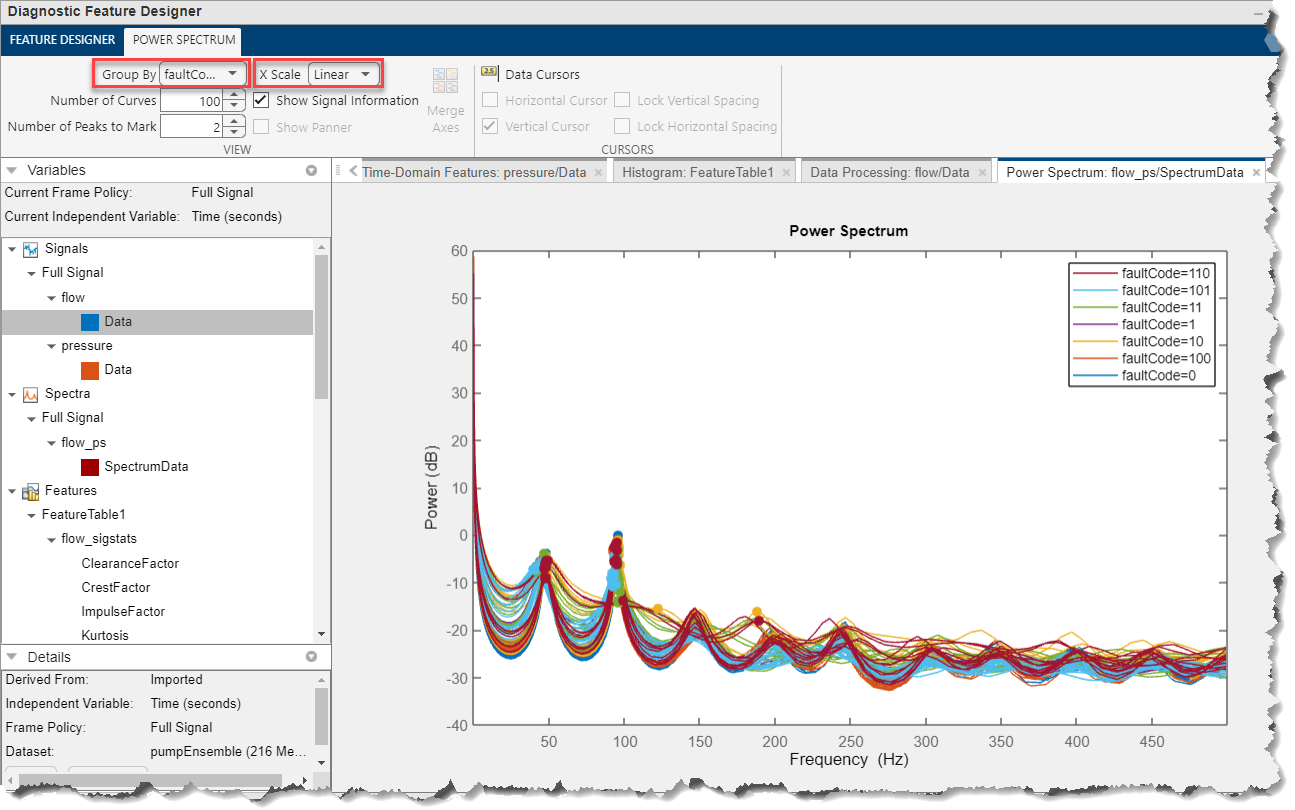

You can see that the spectral peaks are clearly distinguishable. This is what we want to see. 

**Repeat this process for the **`pressure`** signal.**

### 8. Extract Frequency-Domain Features

Once you have the autoregressive spectra for both the pressure and the flow signals, you can compute spectral features such as spectral peaks, modal coefficients and band power. 

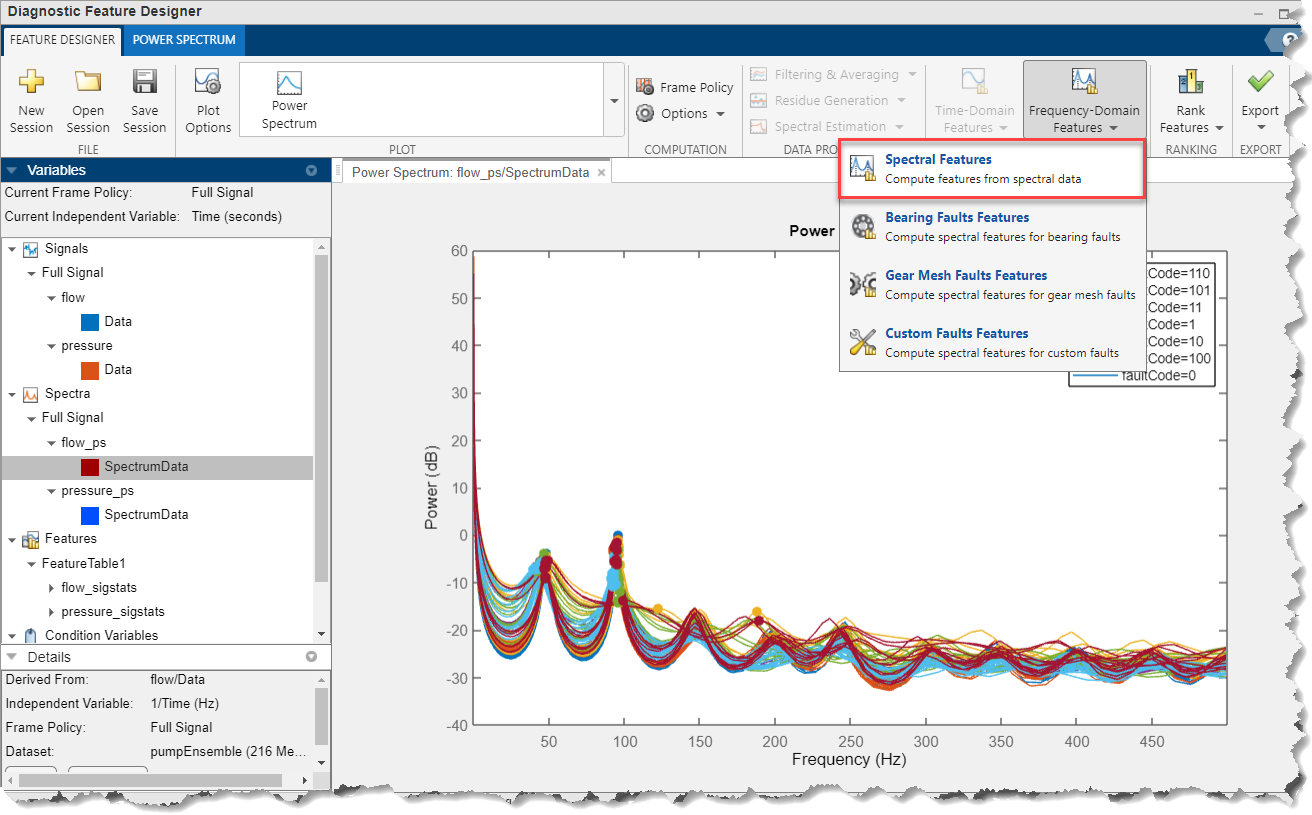

Extract these features in a smaller band of frequencies between `23-250 Hz` as the peaks after `250 Hz` are smaller. It is harder to distinguish the peaks at higher frequencies. Note that you are extracting 5 spectral peaks for each signal.

For now, clear the Plot results check box. You will plot results later to see if the features help distinguish different fault conditions. 

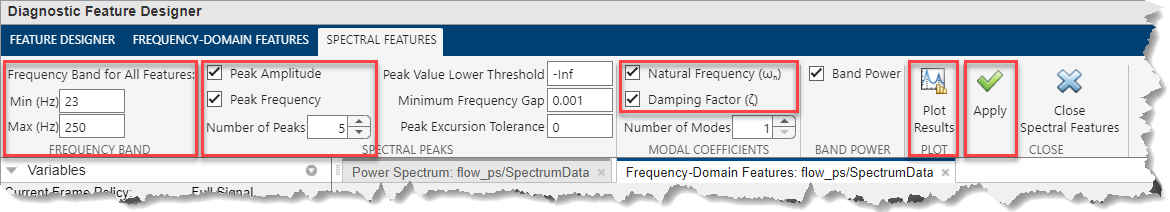

**Repeat this process for the **`pressure`** signal.**

### 9. Visualize Features

All the features you have extracted have been collected in a table shown in the Feature Tables browser. To view the features, select the table `FeatureTable1` and click the *Feature Table View* from the PLOT gallery:

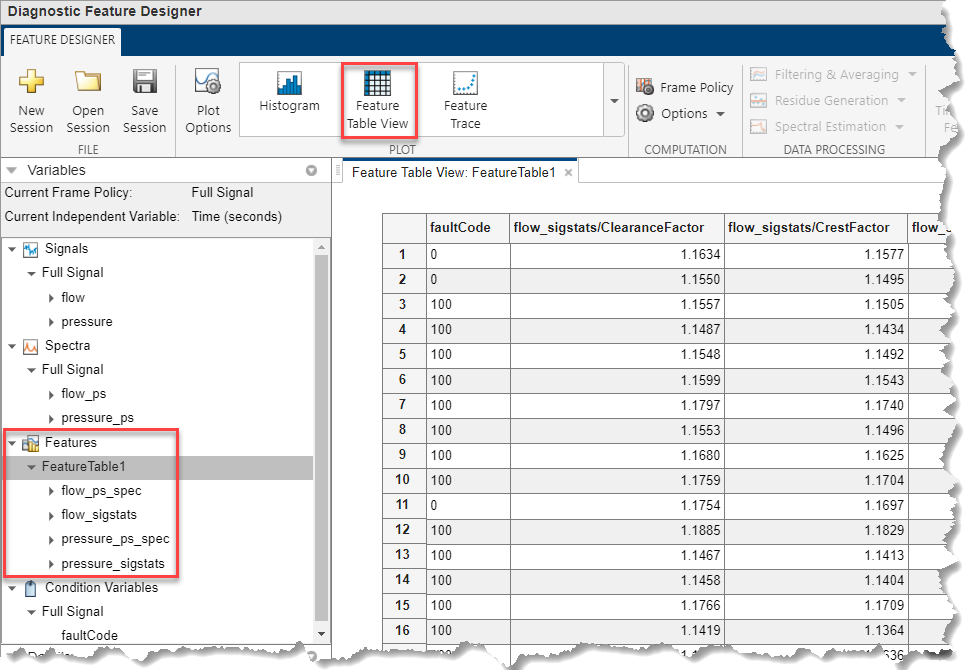

Each row corresponds to a particular dataset in the ensemble, and the column values for that row represent the different feature values for that particular dataset. As you computed more features, more columns got appended to the table. 

When viewed as a histogram (PLOT gallery > *Histogram*), you can see the distributions of the feature values for different condition variable values, i.e. fault types. Histogram plots grouped by fault code can help to determine if certain features are strong differentiators between fault types. If they are strong differentiators, their distributions will be more distant from each other. For the triplex pump, the feature distributions tend to overlap quite a bit. The next section looks at using automated ranking to find which features are more useful for fault prediction.

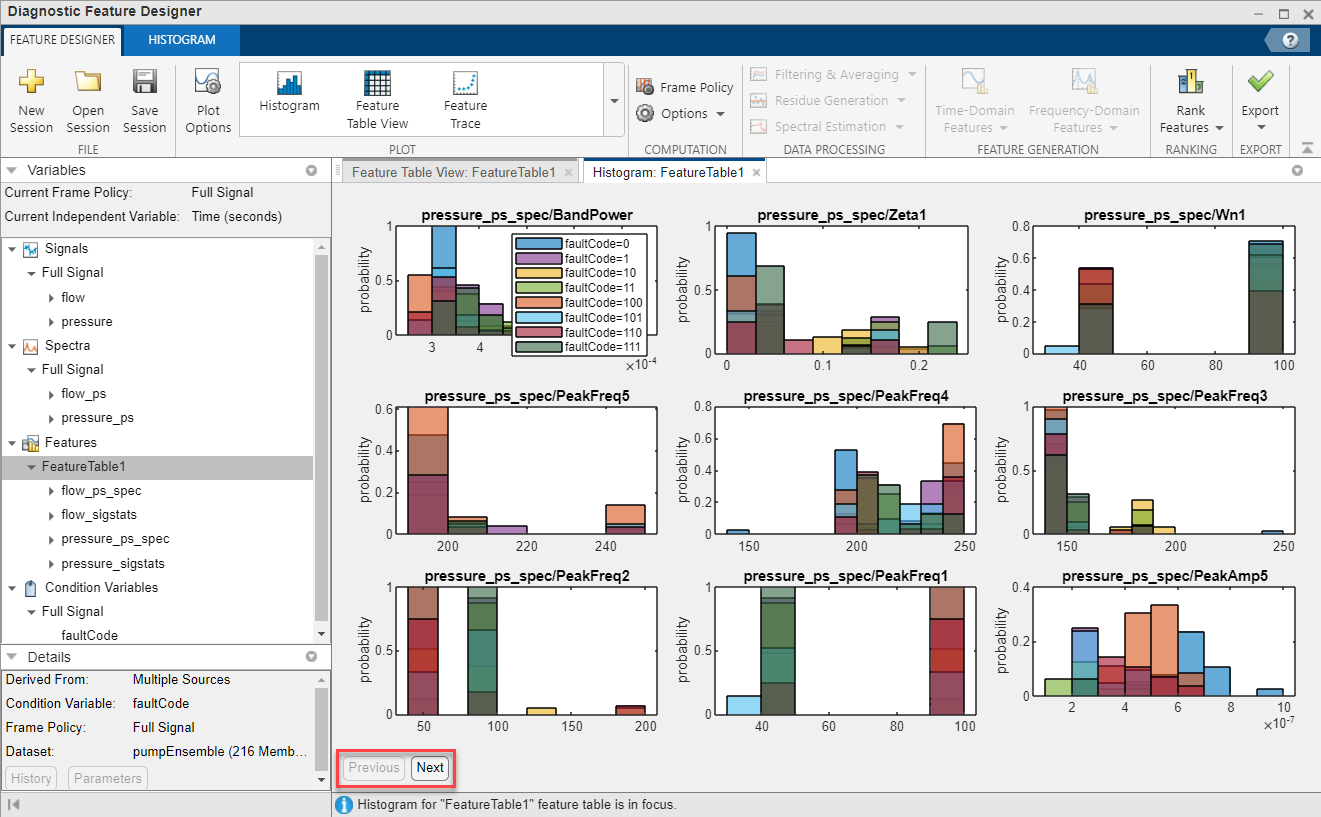

### 10. Rank Features

Now that you've extracted a lot of features, how do you know which ones will be the best candidates for training an accurate machine learning model? In the Diagnostic Feature Designer, you can rank features to determine the likelihood that they will have good predictive power.

Open the *Rank Features* dialog from the FEATURE GENERATION section as shown below and select the current feature table (`FeatureTable1`) you have created.

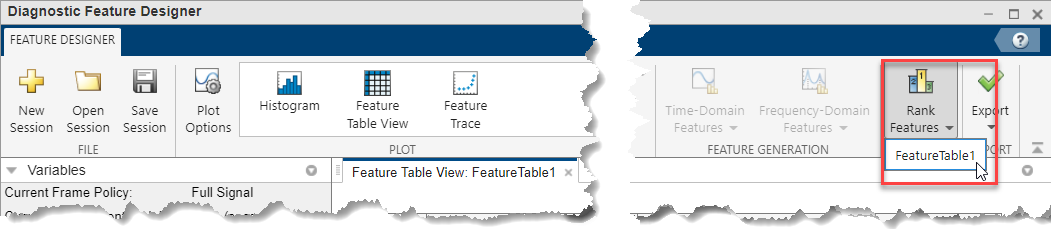

This gathers all the feature data and ranks them based on a metric such as ANOVA. The features are then listed in terms of importance on the basis of the metric value.

In this case, you can see that the RMS value for the flow signal, and the RMS and mean values for the pressure signal are the features that most strongly distinguish different fault types from each other.

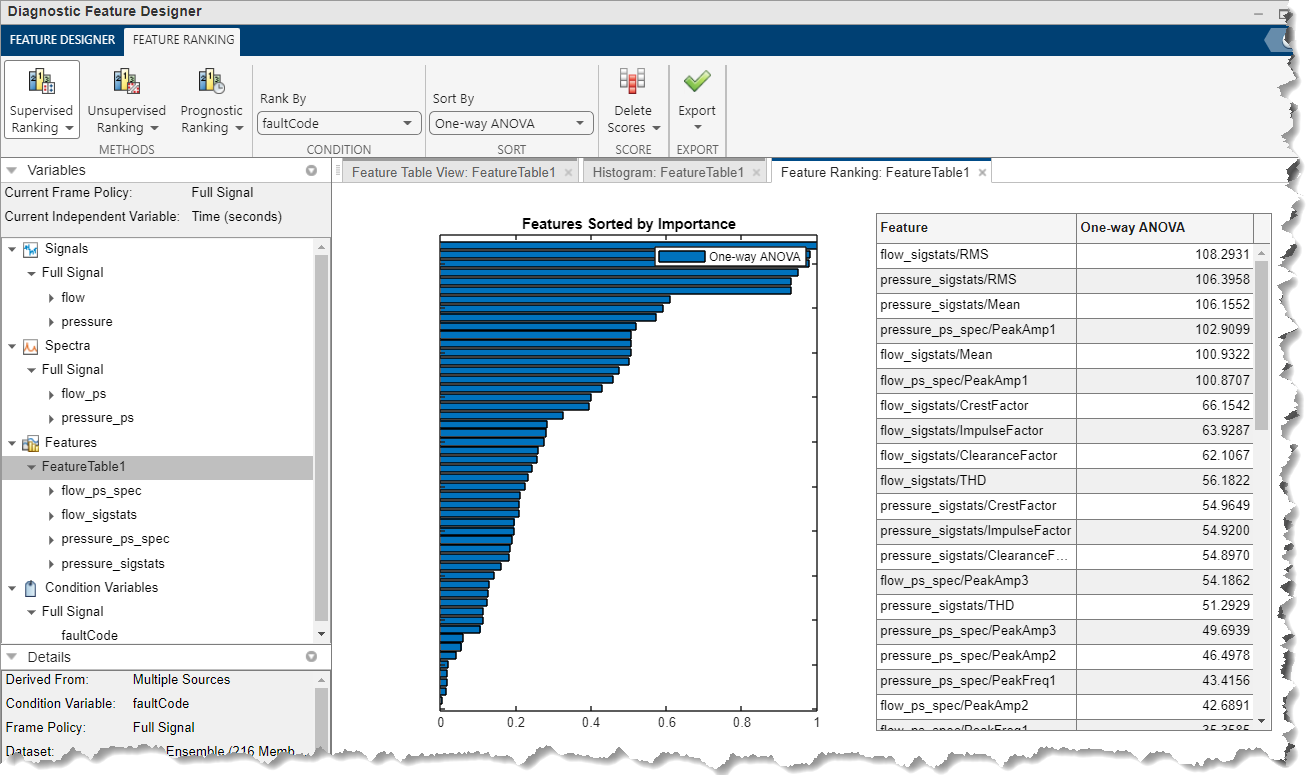

### >>Checkpoint<<

If you would like to catch up to this point, you may run:

### 11. Export Top Features

Once you have ranked your features in terms of importance, the next step is to export the best ones so that you can train a classification model based on these features. 

Click the *Export *dropdown from the FEATURE RANKING tab and choose *Export features to the MATLAB workspace*:

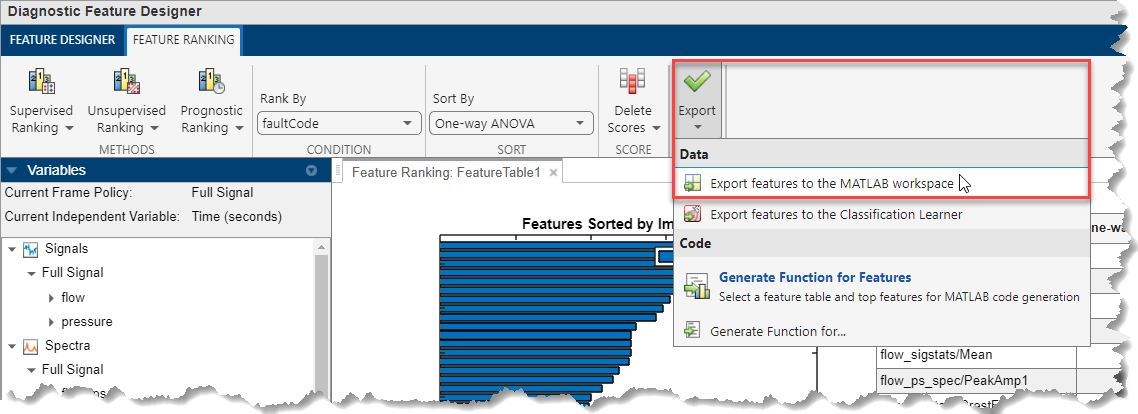

Choose the top `20` features and click Export:

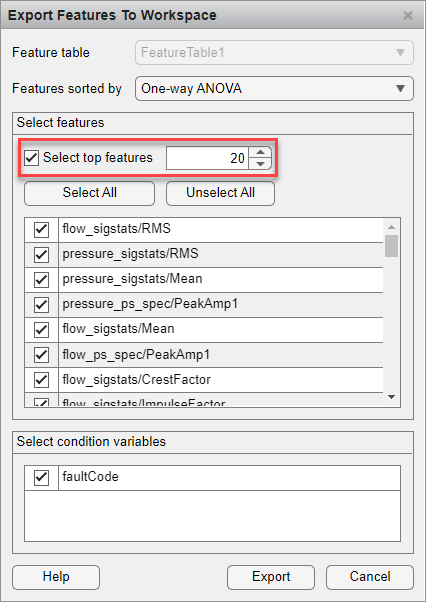

There features are then sent to the MATLAB workspace in the form of a table named `FeatureTable1`.

*Note*: You may also export the features to the Classification Learner app, allowing you to continue with the interactive workflow towards building a machine learning model to design a classifier to identify different faults. However, we'll use a programmatic approach in the rest of this exercise. If there is time at the end of the exercise, you may can try this in the last section (optional). 

### 12. Generate a Function to Recompute Features

Often, you will want to use the same feature extraction computations on new data. To redo all of the work you just did interactively in the app, you can generate a MATLAB function to recompute these features. The app generates code that reproduces both the preliminary data processing, feature extraction, and ranking.

From the *Export* dropdown in the FEATURE RANKING tab select *Generate Function for Features*:

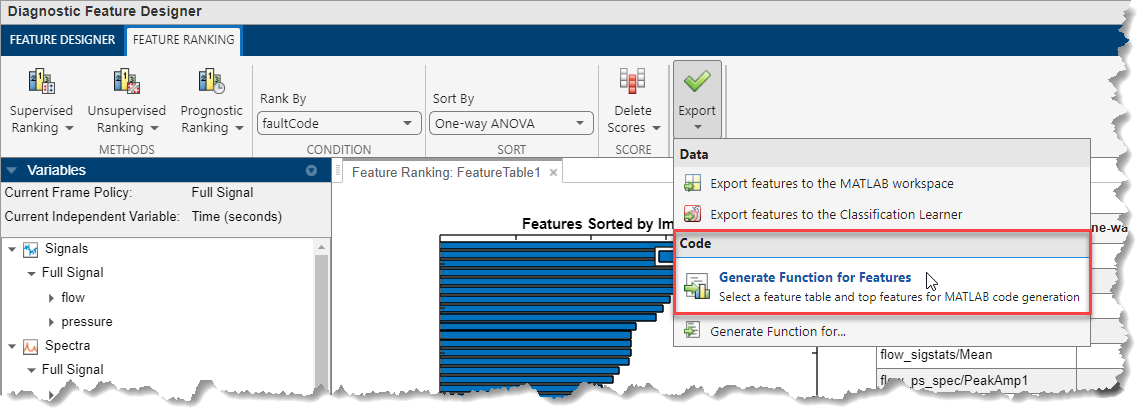

Choose `20` as the Number of Top Features to be used in the generated function:

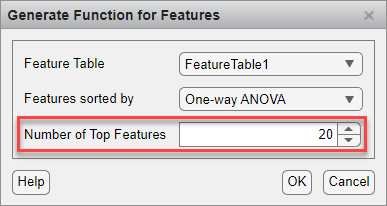

Save the generated function to your current folder.

## Train a Classification Model to Identify Faults

### 13. Recompute Features from Generated Function

We exported a function, diagnosticFeatures, which will recompute all of the features we generated in the Diagnostic Feature Designer earlier. This allows us to use the function on new or larger datasets, or on data as it's acquired from new pumps. 

Compute the features using the generated MATLAB function `diagosticFeatures:`

trainFeatures = diagnosticFeatures(trainData)

trainFeatures = 216×21 table
    faultCode    flow_sigstats/ClearanceFactor    flow_sigstats/CrestFactor    flow_sigstats/ImpulseFactor    flow_sigstats/Mean    flow_sigstats/RMS    flow_sigstats/THD    pressure_sigstats/ClearanceFactor    pressure_sigstats/CrestFactor    pressure_sigstats/ImpulseFactor    pressure_sigstats/Mean    pressure_sigstats/RMS    pressure_sigstats/THD    flow_ps_spec/PeakAmp1    flow_ps_spec/PeakAmp2    flow_ps_spec/PeakAmp3    flow_ps_spec/PeakFreq1    pressure_ps_spec/PeakAmp1    pressure_ps_spec/PeakAmp2    pressure_ps_spec/PeakAmp3    pressure_ps_spec/PeakFreq1
    _________    __

Next, do the same thing to compute features from the test data:

testFeatures = diagnosticFeatures(testData)

testFeatures = 24×21 table
    faultCode    flow_sigstats/ClearanceFactor    flow_sigstats/CrestFactor    flow_sigstats/ImpulseFactor    flow_sigstats/Mean    flow_sigstats/RMS    flow_sigstats/THD    pressure_sigstats/ClearanceFactor    pressure_sigstats/CrestFactor    pressure_sigstats/ImpulseFactor    pressure_sigstats/Mean    pressure_sigstats/RMS    pressure_sigstats/THD    flow_ps_spec/PeakAmp1    flow_ps_spec/PeakAmp2    flow_ps_spec/PeakAmp3    flow_ps_spec/PeakFreq1    pressure_ps_spec/PeakAmp1    pressure_ps_spec/PeakAmp2    pressure_ps_spec/PeakAmp3    pressure_ps_spec/PeakFreq1
    _________    ____

### 14. Train Classification Models

We can now train a variety of classifiers on these features to see which one most accurately predicts the fault codes of the pump. First, train three types of models on the training features:

mdlTree = fitctree(trainFeatures, "faultCode"); 
mdlSVM = fitcecoc(trainFeatures, "faultCode"); 
mdlKNN = fitcknn(trainFeatures, "faultCode");

### 15. Compare Model Performance

To avoid overfitting our training data, we should test the model performance on data it was not trained on -- our test features.

Choose a trained model and view the confusion chart to see how it performed.

mdl = mdlKNN

mdl =   ClassificationKNN
           PredictorNames: {1×20 cell}
             ResponseName: 'faultCode'
    CategoricalPredictors: []
               ClassNames: [0    1    10    11    100    101    110    111]
           ScoreTransform: 'none'
          NumObservations: 216
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


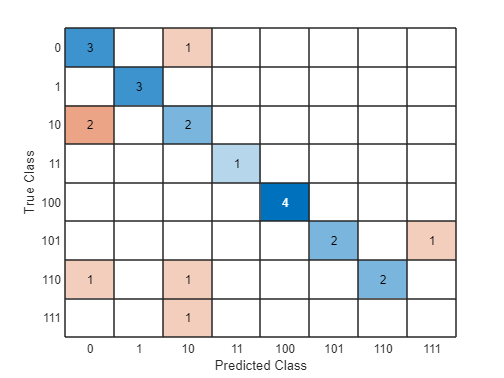

predictTest = predict(mdl, testFeatures);
testGroundTruth = testFeatures.faultCode;
figure;
confusionchart(testGroundTruth, predictTest)

l = loss(mdl, testFeatures, 'faultCode')

l = 0.3009

## [Optional] Train Classification Models using *Classification Learner *app

Instead of training models programmatically, you could also interactively train a variety of classification models using the* Classification Learner* app. To do so, you can export the features directly from the *Diagnostic Feature Designer* to the *Classification Learner*:

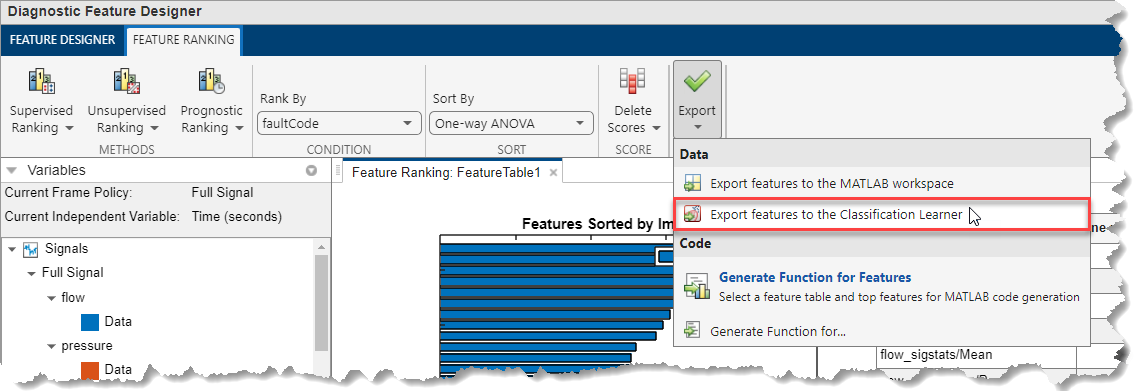

Choose the top `20` features to be exported to Classification Learner app and click *Export*:

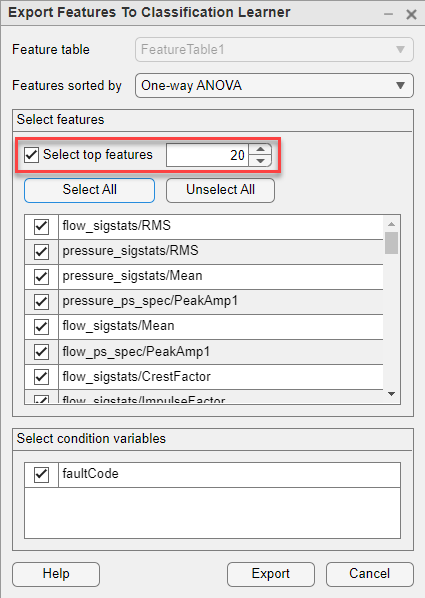

Once features have been exported you may start a new session from the obtained features. Choose Resubstitution Validation as a Validation Scheme. Note that this provides no protection against overfitting. Later you will be able to test the trained models against the independent test dataset.

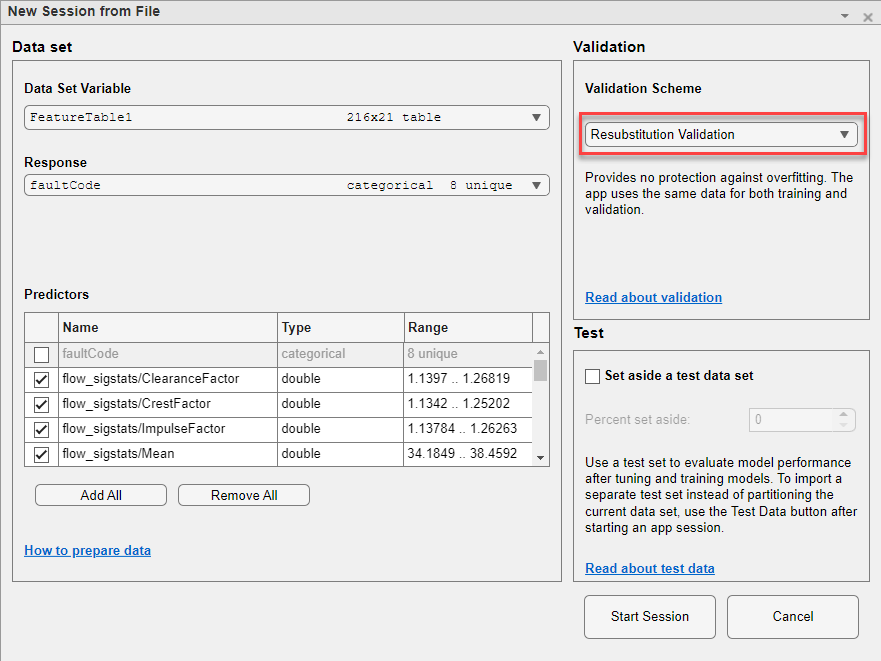

At this point, you may train several Machine Learning models from the MODELS catalog:

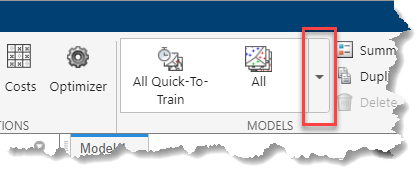

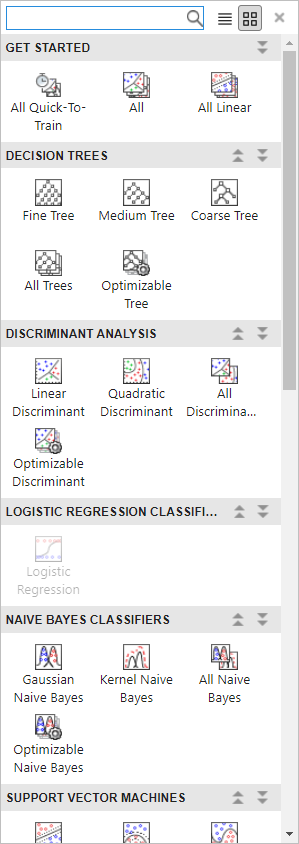

Select and train (play button) a few machine learning models:

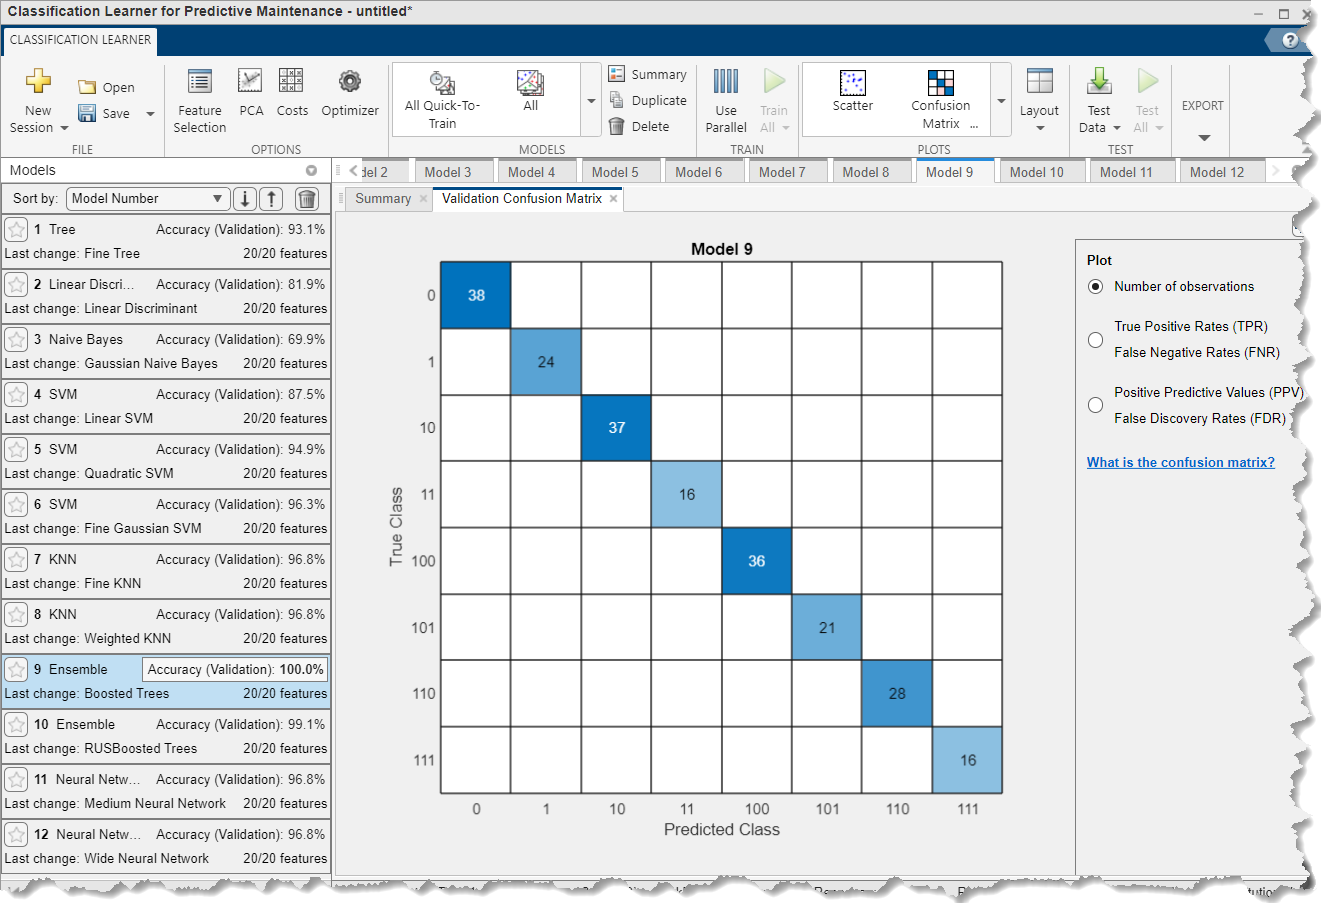

Note that model accuracy is very high for Boosted Trees and other methods. This is likely due to overfitting due to no validation dataset. This was done because our dataset was very small. 

At this point, you can use a new dataset to evaluate the models performance against unseen data:

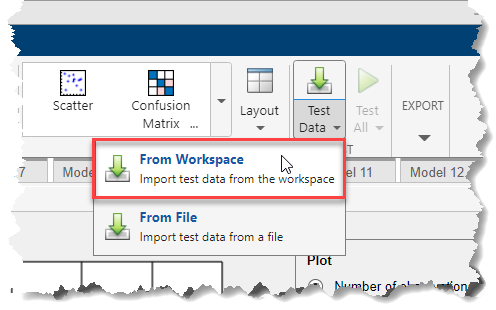

Provide the computed test features (`testFeatures`):

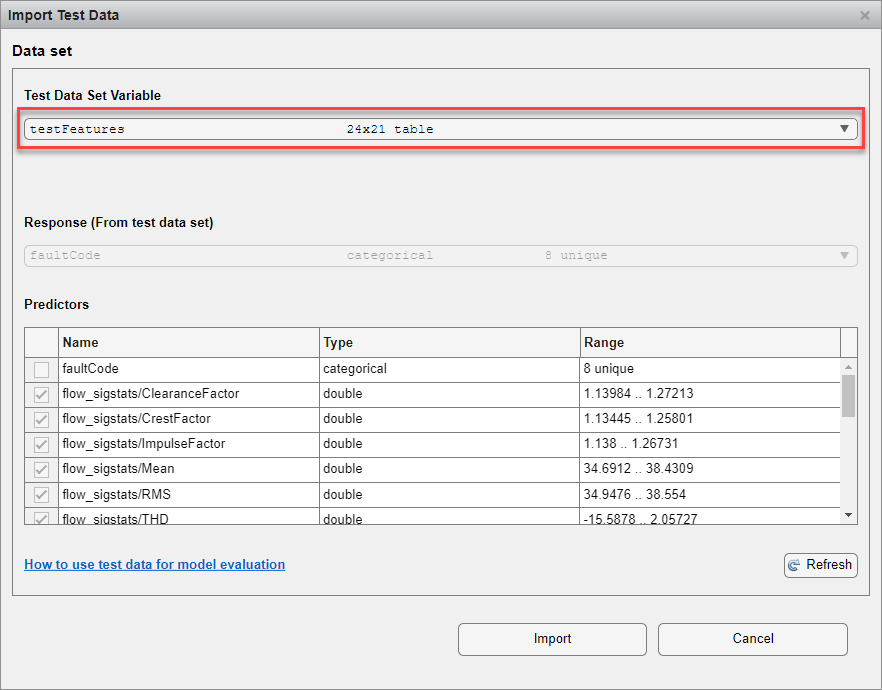

Test all trained models:

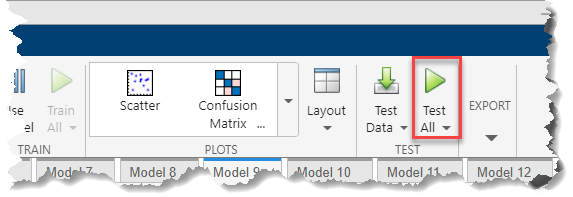

Check what model provides the greatest accuracy against the test data:

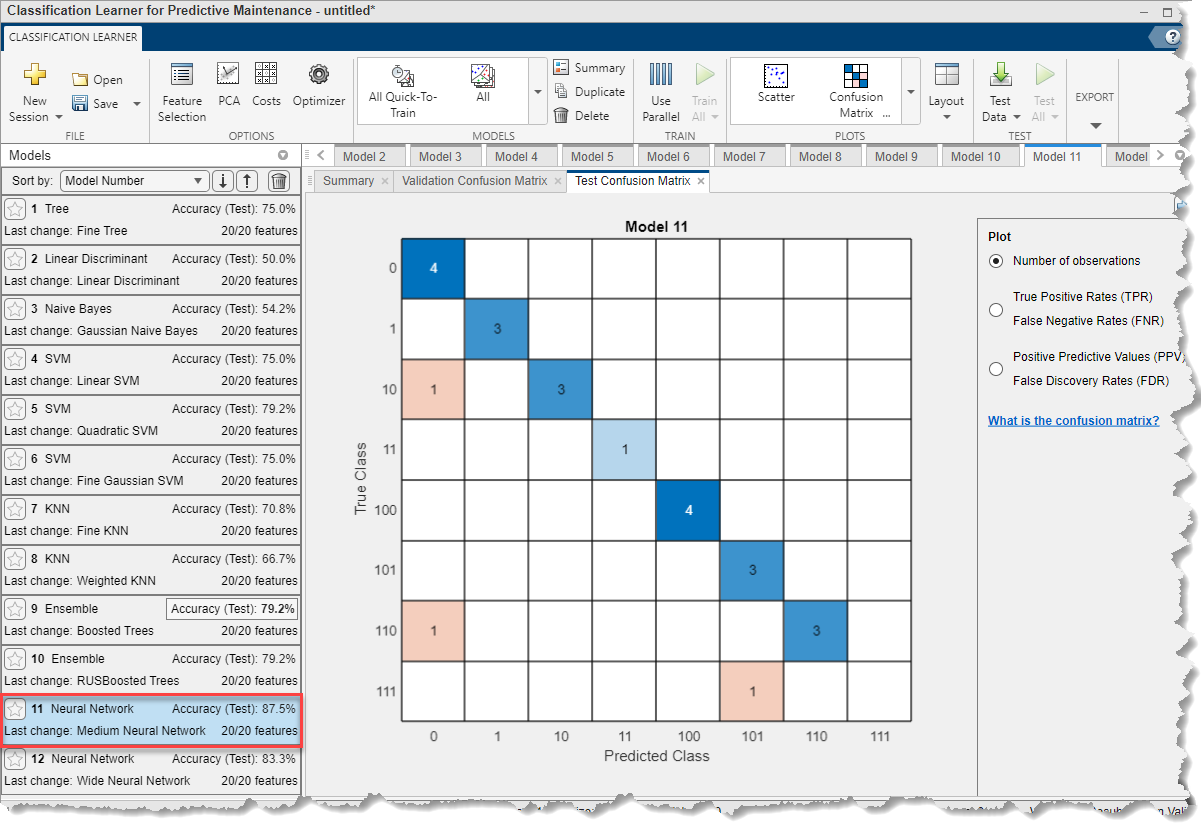

To conclude, you may export the trained model or generate a function to retrain the model:

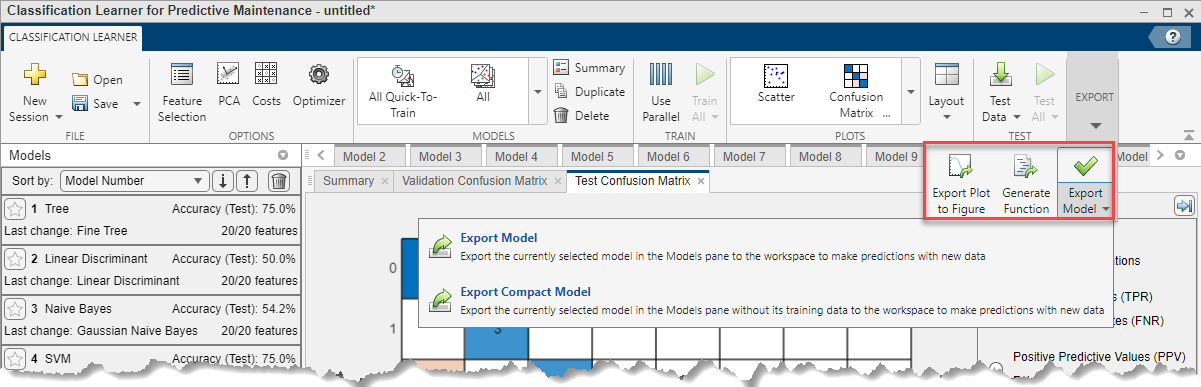

*Copyright 2022 The MathWorks, Inc.*